# Second-Order System – Spring-Mass-Damper Response

## Underdamped Systems

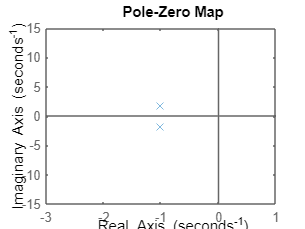

% System parameters
m = 1;      % mass (kg)
c = 2;      % damping (Ns/m)
k = 4;      % spring constant (N/m)

% Transfer function: 1 / (m*s^2 + c*s + k)
num = 1;
den = [m, c, k];
sys = tf(num, den);

% Plot Poles/Zeros
figure
pzmap(sys)
axis([-3 1 -15 15])

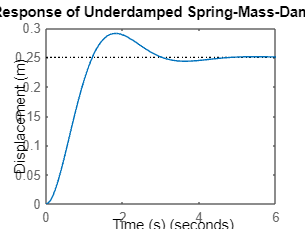


% Plot the step response
figure
step(sys)
title('Step Response of Underdamped Spring-Mass-Damper System');
xlabel('Time (s)');
ylabel('Displacement (m)');


% Show damping and natural frequency
damp(sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00 + 1.73e+00i     5.00e-01       2.00e+00         1.00e+00    
 -1.00e+00 - 1.73e+00i     5.00e-01       2.00e+00         1.00e+00    


## Undamped Systems

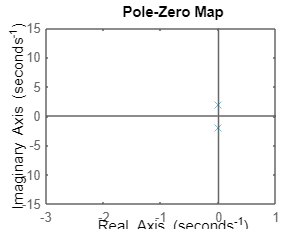

% System parameters
m = 1;      % mass (kg)
c = 0;      % damping (Ns/m)
k = 4;      % spring constant (N/m)

% Transfer function: 1 / (m*s^2 + c*s + k)
num = 1;
den = [m, c, k];
sys = tf(num, den);

% Plot Poles/Zeros
figure
pzmap(sys)
axis([-3 1 -15 15])

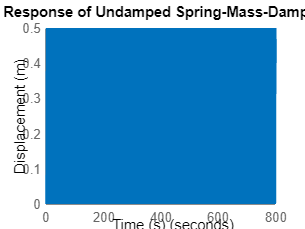


% Plot the step response
figure
step(sys)
title('Step Response of Undamped Spring-Mass-Damper System');
xlabel('Time (s)');
ylabel('Displacement (m)');


% Show damping and natural frequency
damp(sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00 + 2.00e+00i     0.00e+00       2.00e+00           Inf       
  0.00e+00 - 2.00e+00i     0.00e+00       2.00e+00           Inf       


## **Overdamped** Systems

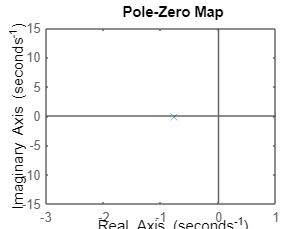

% System parameters
m = 1;      % mass (kg)
c = 6;      % damping (Ns/m)
k = 4;      % spring constant (N/m)

% Transfer function: 1 / (m*s^2 + c*s + k)
num = 1;
den = [m, c, k];
sys = tf(num, den);

% Plot Poles/Zeros
figure
pzmap(sys)
axis([-3 1 -15 15])

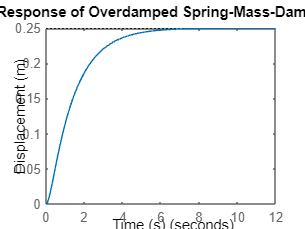


% Plot the step response
figure
step(sys)
title('Step Response of Overdamped Spring-Mass-Damper System');
xlabel('Time (s)');
ylabel('Displacement (m)');


% Show damping and natural frequency
damp(sys)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -7.64e-01     1.00e+00       7.64e-01         1.31e+00    
 -5.24e+00     1.00e+00       5.24e+00         1.91e-01    


## **Critically-Damped** Systems

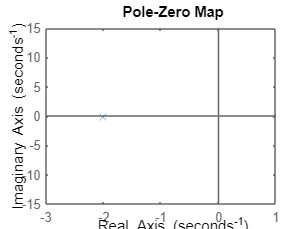

% System parameters
m = 1;      % mass (kg)
c = 4;      % damping (Ns/m)
k = 4;      % spring constant (N/m)

% Transfer function: 1 / (m*s^2 + c*s + k)
num = 1;
den = [m, c, k];
sys = tf(num, den);

% Plot Poles/Zeros
figure
pzmap(sys)
axis([-3 1 -15 15])

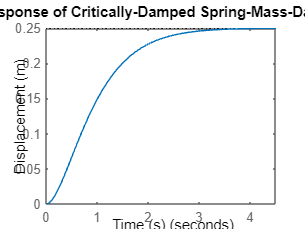


% Plot the step response
figure
step(sys)
title('Step Response of Critically-Damped Spring-Mass-Damper System');
xlabel('Time (s)');
ylabel('Displacement (m)');


% Show damping and natural frequency
damp(sys)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    


% Have you noticed, why does damp() command still return damping of 1?